load("test_functions2.mat", '-mat')


# Function 1

c1 = 1e-4;
rho = 0.8;
btmax = 50;
disp_int = [-20 20]

disp_int =    -20    20


x_start = [-15 -5]'

x_start =    -15
    -5


[xk,fk,gradfk_norm,k,xseq,btseq] = newton_backtrack(x_start,f1,gradf1,Hessf1,kmax,tolgrad,c1,rho,btmax,true);

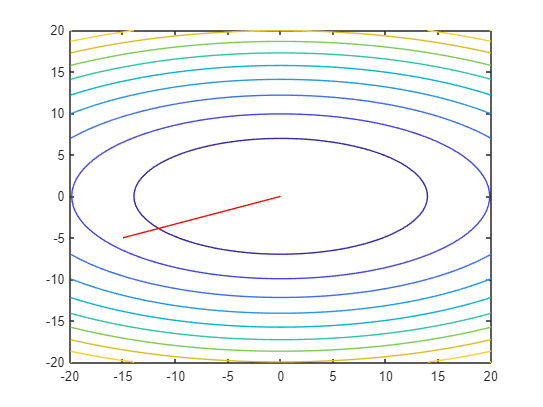

f1_meshgrid = @(X,Y)reshape(f1([X(:),Y(:)]'),size(X));
fcontour(f1_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

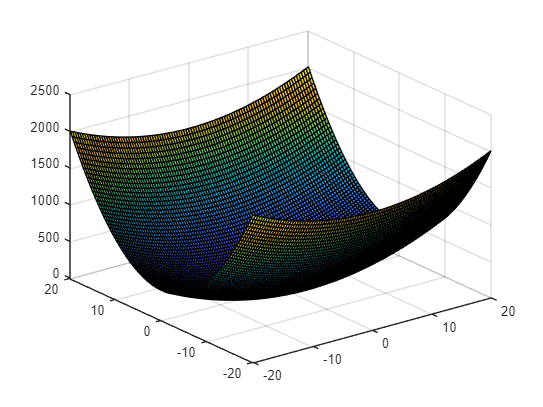

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f1_surf = f1_meshgrid(X,Y);

surf(X,Y,f1_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f1_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

# Function 2

c1 = 1e-4;
rho = 0.8;
btmax = 50;
disp_int = [-50 50]

disp_int =    -50    50


x_start = x0

x_start =     -5
    -5


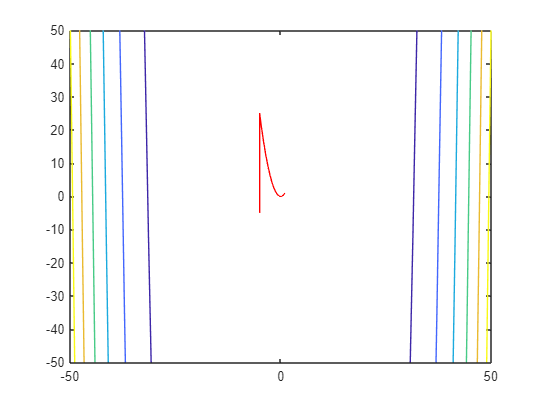

[xk,fk,gradfk_norm,k,xseq,btseq] = newton_backtrack(x_start,f2,gradf2,Hessf2,kmax,tolgrad,c1,rho,btmax,true);

% Contour
f2_meshgrid = @(X,Y) reshape(f2([X(:),Y(:)]'),size(X));
fcontour(f2_meshgrid, disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

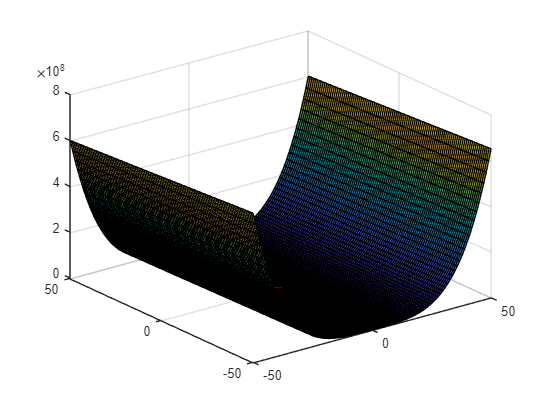


% Surface
x = linspace(-50,50);
y = linspace(-50,50);
[X,Y] = meshgrid(x,y);
f2_surf = f2_meshgrid(X,Y);


surf(X,Y,f2_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f2_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

# Function 3

c1 = 1e-4;
rho = 0.8;
btmax = 50;
disp_int = [-20 20]

disp_int =    -20    20


x_start = [10 -20]';
[xk,fk,gradfk_norm,k,xseq,btseq] = newton_backtrack(x_start,f3,gradf3,Hessf3,kmax,tolgrad,c1,rho,btmax,true)

xk =     3.5107
   -1.6683


fk = 0.6162

gradfk_norm = 15.0792

k = 1000

xseq =    10.0000    6.9210    5.0243    4.0130    3.6613    3.5991    3.5562    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116    3.5116
  -20.0000  -13.4818   -9.1602   -6.3052   -4.4230   -3.1760   -2.3245   -1.6785   -1.6785   -1.6785   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6784   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6783   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6782   -1.6781   -1.6781   -1.6781   -1.6781   -1.6781   -1.6781   -1.6781   -1.6781   -1.6781  

btseq =      0     0     0     0     0     0     0    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50


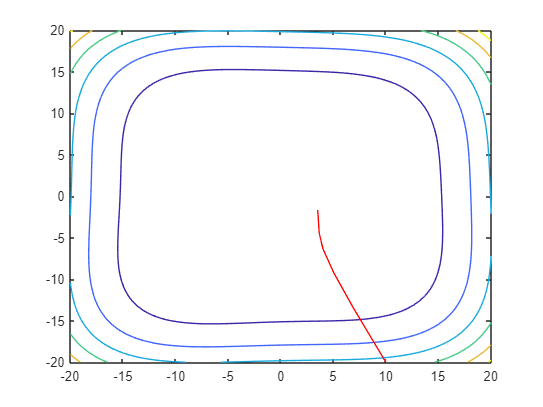


% Contour
f3_meshgrid = @(X,Y) reshape(f3([X(:),Y(:)]'),size(X));
fcontour(f3_meshgrid, disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

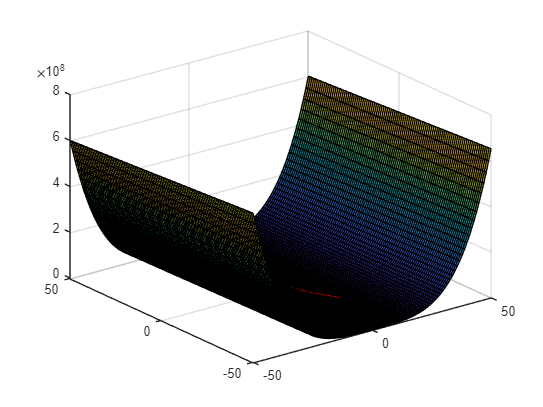


% Surface
x = linspace(-50,50);
y = linspace(-50,50);
[X,Y] = meshgrid(x,y);
f2_surf = f2_meshgrid(X,Y);


surf(X,Y,f2_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f2_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off